# Demo: BER over Flat and Fading Channels

In this demo, you will learn to:

- Modulate M-QAM symbols

- Simulate flat and fading channels on a symbol level

- Equalize and demodulate the symbols over the channel

- Measure the bit error rate (BER)

## Uncoded BER over a Flat Channel

We first compute the BER of 16-QAM over a channel without fading.  To do this, we first create test set of bits.

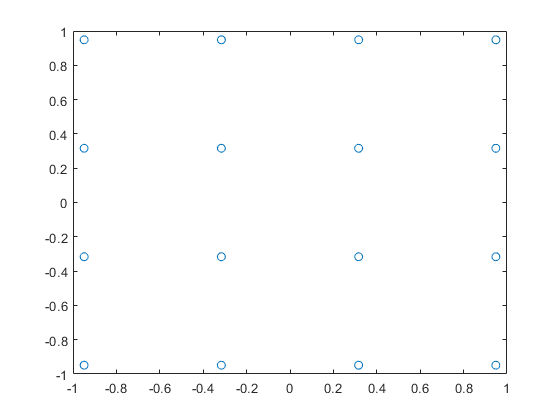

% Parameters
bitsPerSym = 4; % 4=16-QAM
nsym = 10000;

% Create random bits to test
nbits = nsym*bitsPerSym;
bits = randi([0,1], nbits, 1);

% Modulate to M-QAM
M = 2^bitsPerSym;
s = qammod(bits,M,'UnitAveragePower', true, 'Input', 'bit');
plot(real(s), imag(s), 'o');

We next loop over the SNR levels.  For each SNR, we add noise, demodulate and measure the BER

% SNR levels to test
EbN0Test = (-5:11)';
ntest = length(EbN0Test);

% TX symbol energy
Es = mean(abs(s).^2);
ber = zeros(ntest,1);

for i = 1:ntest
    
    % Add the noise
    EbN0 = EbN0Test(i);
    chan = comm.AWGNChannel("BitsPerSymbol", bitsPerSym, 'EbNo', EbN0, ...
        'SignalPower', Es);
    r = chan.step(s);
    
    % Demodulate
    bitsEst = qamdemod(r,M,'UnitAveragePower',true,'Output','bit');
    
    % Measure the BER
    ber(i) = mean(bitsEst ~= bits);
    fprintf(1, 'EbN0=%7.2f BER=%12.4e\n', EbN0, ber(i));
    
    % Break if zero since higher SNRs should also be zero
    if (ber(i) == 0)
        break
    end
end

EbN0=  -5.00 BER=  2.5925e-01
EbN0=  -4.00 BER=  2.3897e-01
EbN0=  -3.00 BER=  2.1407e-01
EbN0=  -2.00 BER=  1.8857e-01
EbN0=  -1.00 BER=  1.6460e-01
EbN0=   0.00 BER=  1.4165e-01
EbN0=   1.00 BER=  1.2185e-01
EbN0=   2.00 BER=  9.8550e-02
EbN0=   3.00 BER=  7.9400e-02
EbN0=   4.00 BER=  5.8700e-02
EbN0=   5.00 BER=  4.2750e-02
EbN0=   6.00 BER=  2.8150e-02
EbN0=   7.00 BER=  1.7500e-02
EbN0=   8.00 BER=  9.2250e-03
EbN0=   9.00 BER=  4.0000e-03
EbN0=  10.00 BER=  1.6000e-03
EbN0=  11.00 BER=  6.5000e-04


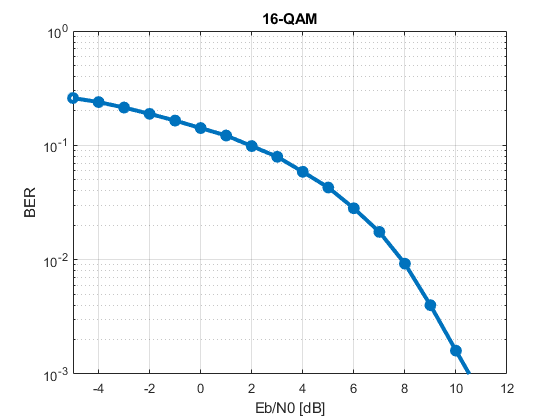

% Plot the results
semilogy(EbN0Test, ber, 'o-', 'LineWidth', 3);
ylim([1e-3,1]);
xlim([-5,12]);
xlabel('Eb/N0 [dB]');
ylabel('BER');
grid on;
title('16-QAM')

## BER with Fading

We now repeat the same experiment with both an AWNG (flat) and fading channel.

% SNR levels to test
EbN0Test = (-5:20)';
nsnr = length(EbN0Test);

% Fading types to test
fadeTest = [false, true];
nfade = length(fadeTest);

% TX symbol energy
Es = mean(abs(s).^2);
ber = zeros(nsnr,nfade);


for ifade = 1:nfade
    fade = fadeTest(ifade);
    
    for i = 1:nsnr
        % Generate fading channel
        if fade
            h = sqrt(1/2)*(randn(nsym,1) + 1i*randn(nsym,1));
        else
            h = ones(nsym,1);
        end
        rxSig0 = s.*h;
        
        
        % Add the noise
        EbN0 = EbN0Test(i);
        chan = comm.AWGNChannel("BitsPerSymbol", bitsPerSym, ...
            'EbNo', EbN0, 'SignalPower', Es);
        rxSig = chan.step(rxSig0);
        
        % Equalize
        z = rxSig ./ h;
        
        % Demodulate
        bitsEst = qamdemod(z,M,'UnitAveragePower',true,'Output','bit');
        
        % Measure the BER
        ber(i,ifade) = mean(bitsEst ~= bits);
        fprintf(1, 'fading=%d EbN0=%7.2f BER=%12.4e\n', fade, EbN0, ber(i,ifade));
        
        % Break if zero since higher SNRs also be zero
        if (ber(i,ifade) == 0)
            break
        end
    end
end

fading=0 EbN0=  -5.00 BER=  2.6080e-01
fading=0 EbN0=  -4.00 BER=  2.3797e-01
fading=0 EbN0=  -3.00 BER=  2.1550e-01
fading=0 EbN0=  -2.00 BER=  1.8852e-01
fading=0 EbN0=  -1.00 BER=  1.6430e-01
fading=0 EbN0=   0.00 BER=  1.4410e-01
fading=0 EbN0=   1.00 BER=  1.1962e-01
fading=0 EbN0=   2.00 BER=  9.7400e-02
fading=0 EbN0=   3.00 BER=  7.7875e-02
fading=0 EbN0=   4.00 BER=  5.9825e-02
fading=0 EbN0=   5.00 BER=  4.2550e-02
fading=0 EbN0=   6.00 BER=  2.8500e-02
fading=0 EbN0=   7.00 BER=  1.6625e-02
fading=0 EbN0=   8.00 BER=  9.7250e-03
fading=0 EbN0=   9.00 BER=  3.9500e-03
fading=0 EbN0=  10.00 BER=  1.8750e-03
fading=0 EbN0=  11.00 BER=  8.5000e-04
fading=0 EbN0=  12.00 BER=  1.5000e-04
fading=0 EbN0=  13.00 BER=  2.5000e-05
fading=0 EbN0=  14.00 BER=  0.0000e+00
fading=1 EbN0=  -5.00 BER=  2.9800e-01
fading=1 EbN0=  -4.00 BER=  2.7897e-01
fading=1 EbN0=  -3.00 BER=  2.5907e-01
fading=1 EbN0=  -2.00 BER=  2.4135e-01
fading=1 EbN0=  -1.00 BER=  2.1998e-01
fading=1 EbN0=   0.00 BER

We plot the results.  We see that there is a large gap between the flat and fading channel performance.

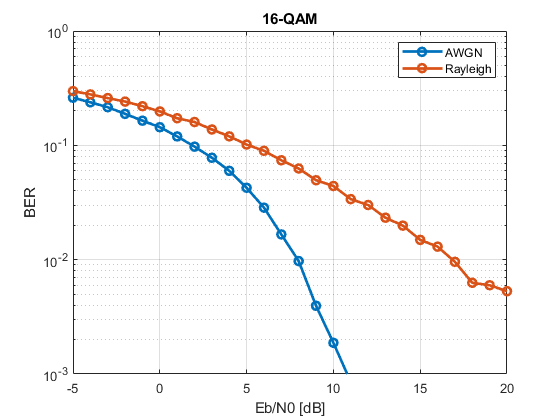

% Plot the results
clf;
semilogy(EbN0Test, ber, 'o-', 'LineWidth', 2);
ylim([1e-3,1]);
xlim([-5,20]);
xlabel('Eb/N0 [dB]');
ylabel('BER');
grid on;
legend('AWGN', 'Rayleigh');
title('16-QAM');